## **Hough transform example with lines **

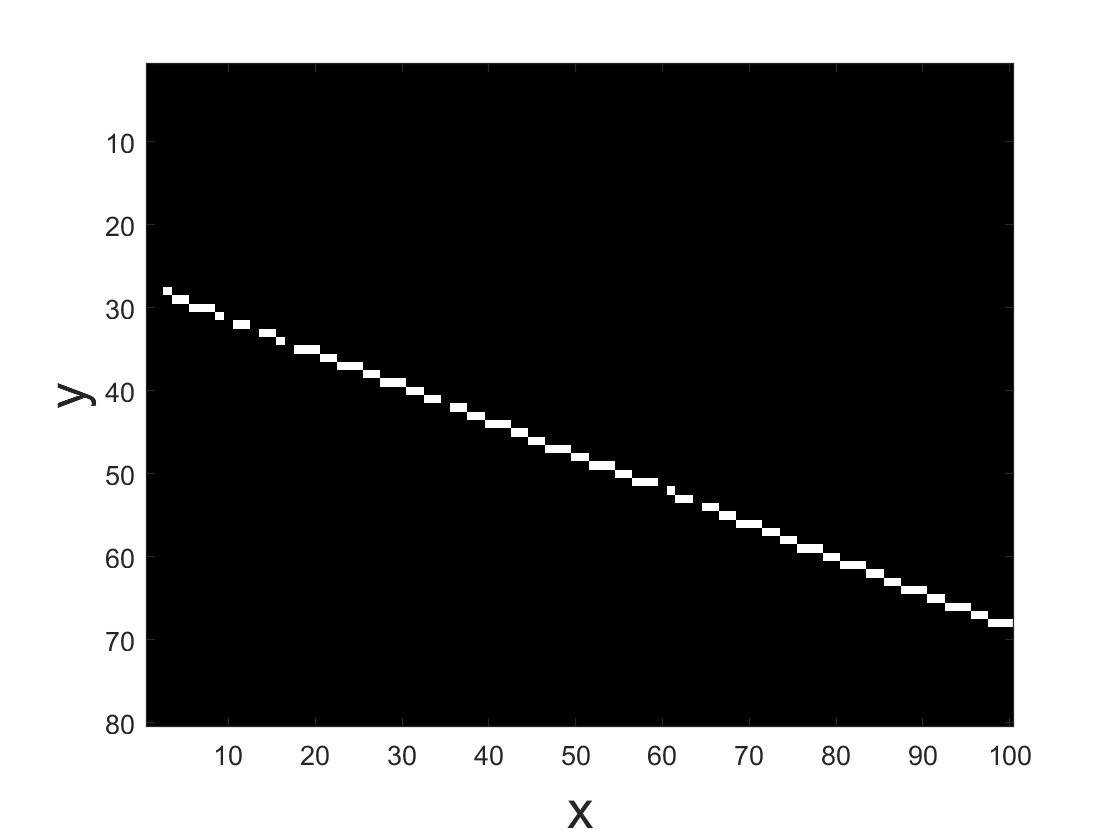

clear; 

N_R     = 250;
N_Theta = 360;

% size of the image
N_X = 100;
N_Y = 80;
I = zeros(N_Y, N_X);

%  make binary image consisting of a set of sample points on a line
%  defined by (r,theta) i.e.    x cos(theta) + y sin(theta) = r

r_0      =  25;      %  distance from (0,0) i.e. (1,1) is top left corner 
theta_0  =  5*pi/8;  %  perpendicular direction (x is to right, y is down)

if (theta_0 == 0)   %  x = constant, so slope is infinite
    display(["code doesn't work for theta 0"]);
    return
end
for x = 1:N_X
     %   r = (x - x0) * cos(theta) + (y - y0) * sin(theta)
     %   where theta is direction perpendicular to line.
     y = round((r_0 - cos(theta_0) * x)/ sin(theta_0)) ;
     if y > 0 && y <= N_Y && rand > .1
         I(y, x) = 1;
     end
end

imagesc(I)
xlabel('x','FontSize',20);  ylabel('y','FontSize',20);
colormap gray

Plot Hough transform of one line.

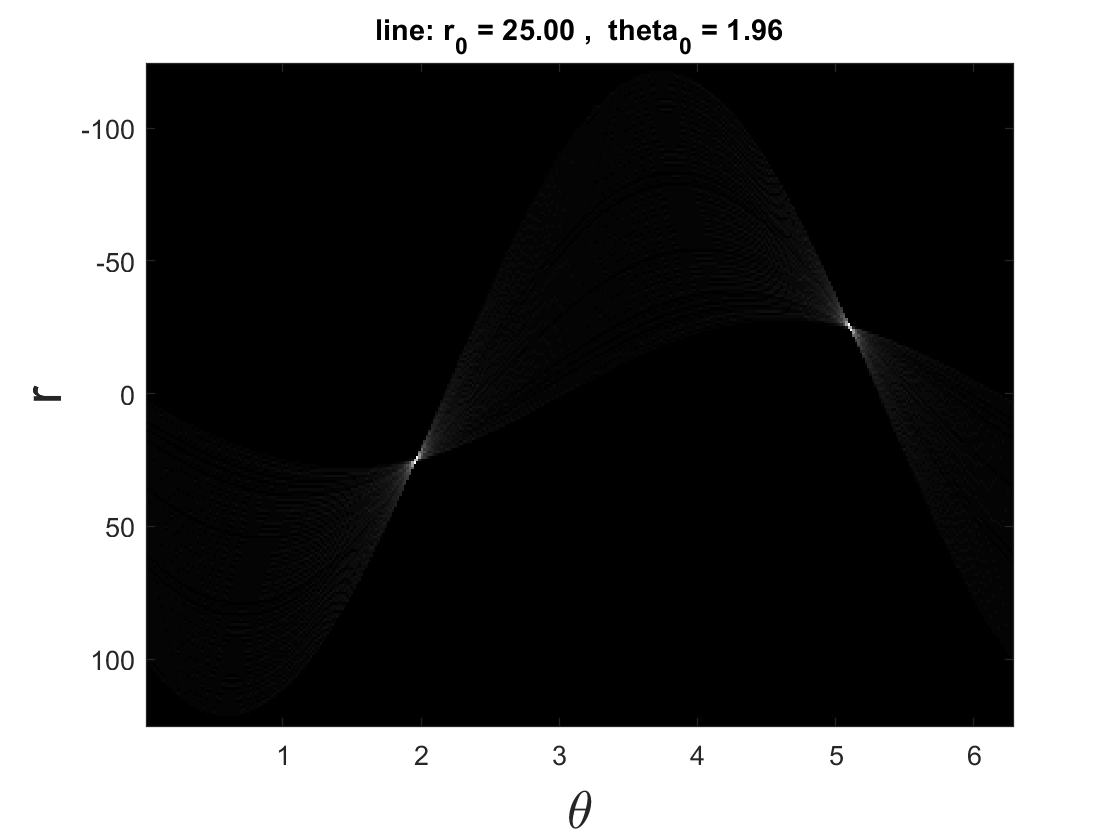

H_r_theta = houghTransform(I, N_Theta, N_R);
txt = sprintf('line: r_0 = %.2f ,  theta_0 = %.2f', r_0, theta_0);
title(txt);

Add a second line.   Note that the slope is higher on the second line, and so because we are defining our line by stepping in the x direction,  we skip over some y values.   (We could avoid this by stepping in the y direction, but I wanted to illustrate something here so I'll stick with this.)

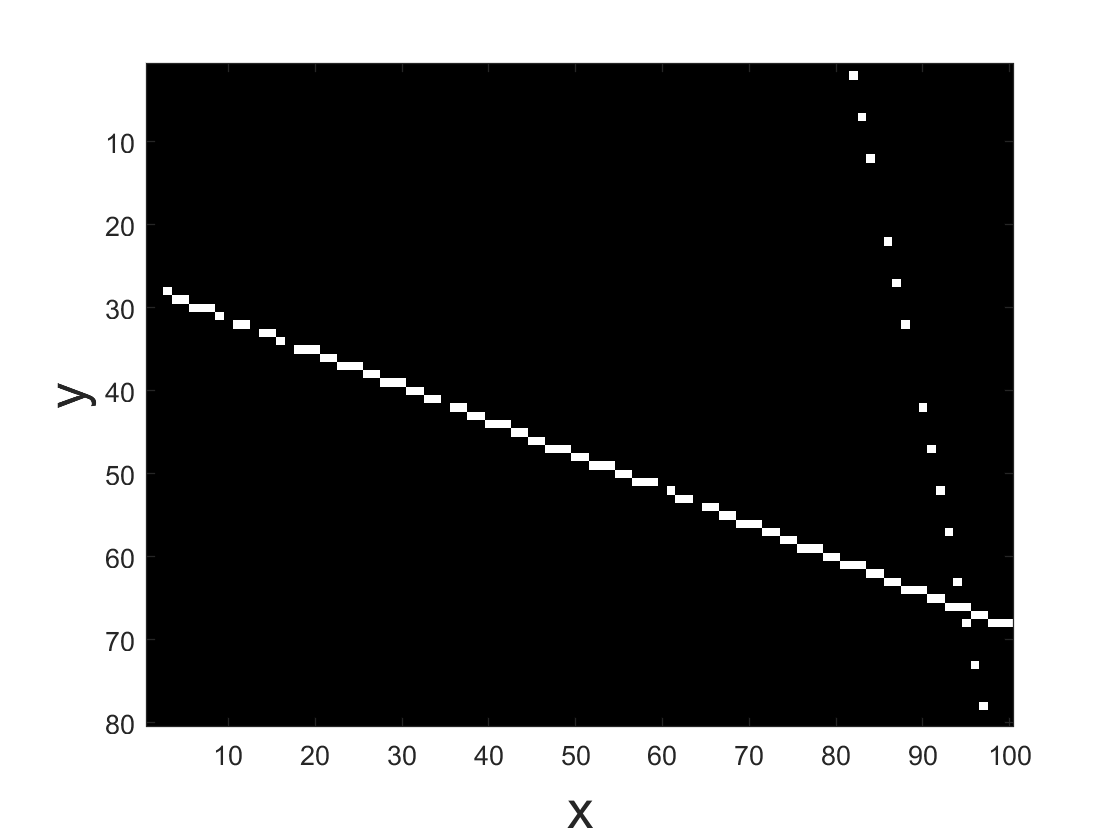

r_0      =  80;
theta_0  =  31*pi/16;    %  perpendicular direction
if (theta_0 == 0)
    display(["code doesn't work for theta 0"]);
    return
end
for x = 1:N_X
    y = round((r_0 - cos(theta_0) * x)/ sin(theta_0)) ;
    if y > 0 && y <= N_Y && rand > .1
        I(y, x) = 1;
    end
end
  
imagesc(I)
xlabel('x','FontSize',20);  ylabel('y','FontSize',20);
colormap gray

Compute and plot Hough transform again with image having two lines.   The resulting Hough transform does have an extra two peaks for the second line (total of four peaks), but the new peaks are not as high because there are fewer pixels on the second line.   

H_r_theta = houghTransform(I, N_Theta, N_R);
txt = sprintf('second line: r_0 = %.2f ,  theta_0 = %.2f', r_0, theta_0)

txt = 'second line: r_0 = 80.00 ,  theta_0 = 6.09'

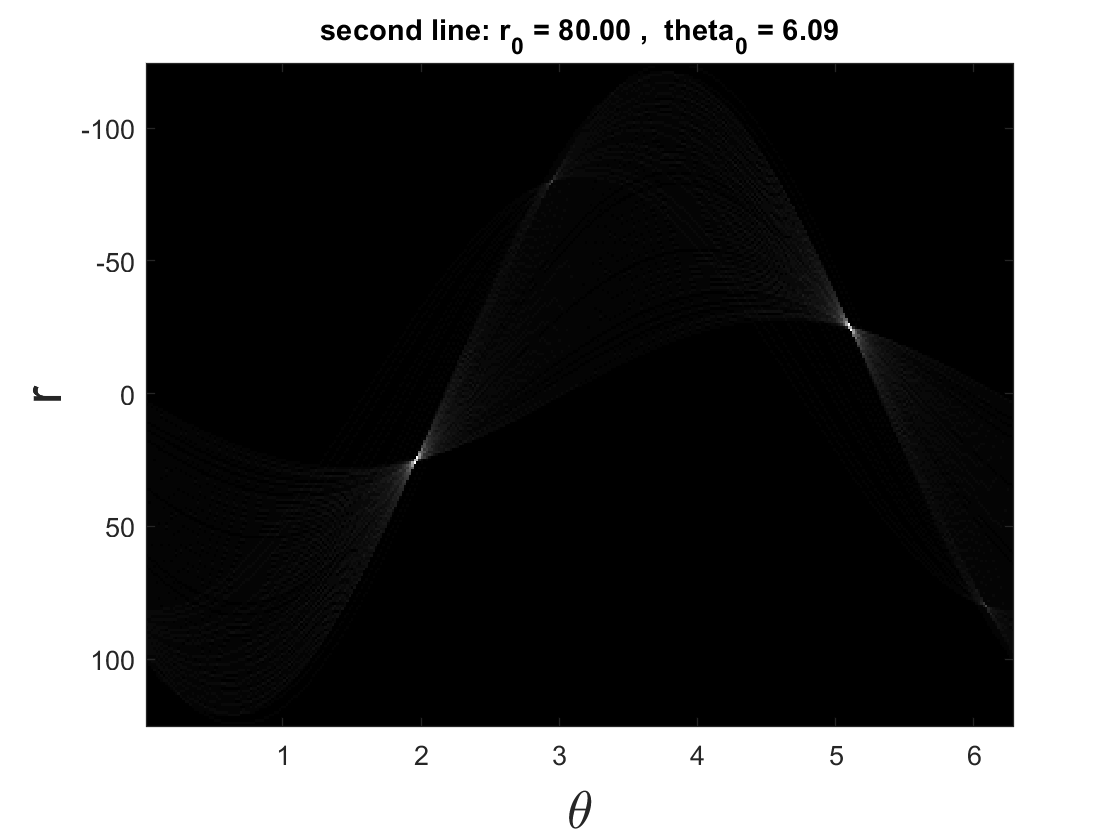

title(txt)

Now let's add some random points.   

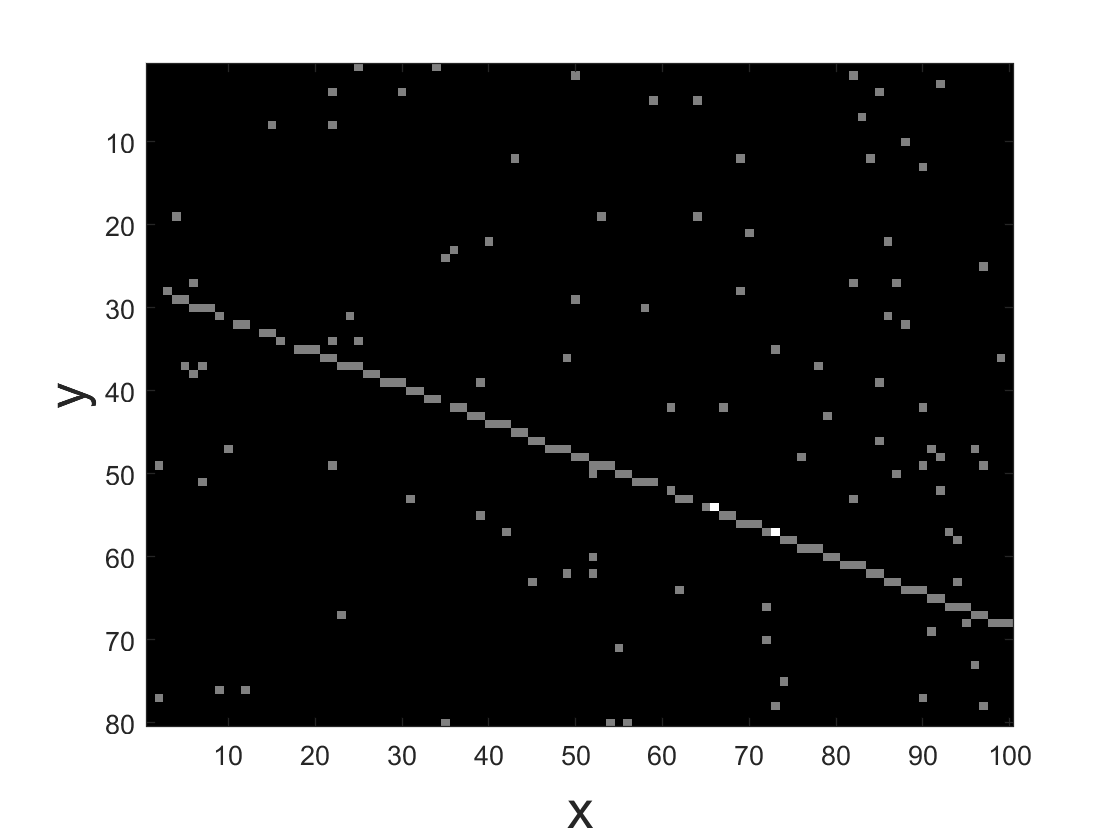

%  add noise points

I = I + (rand(N_Y, N_X) > .99);
imagesc(I)
xlabel('x','FontSize',20);  ylabel('y','FontSize',20);
colormap gray

And again plot the Hough transform.    The noise somewhat hides the second line in the image,  and it also hides the peak of the Hough transform.

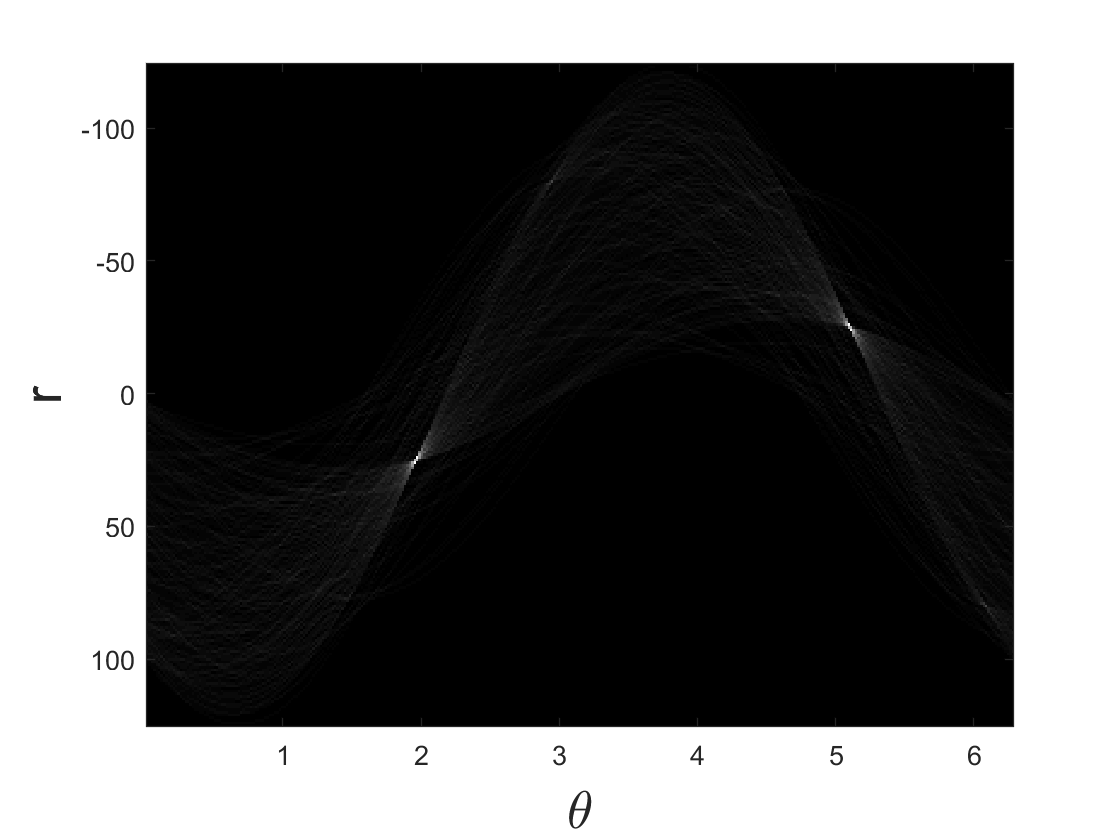

H_r_theta = houghTransform(I, N_Theta, N_R);

Here is the Matlab builtin function

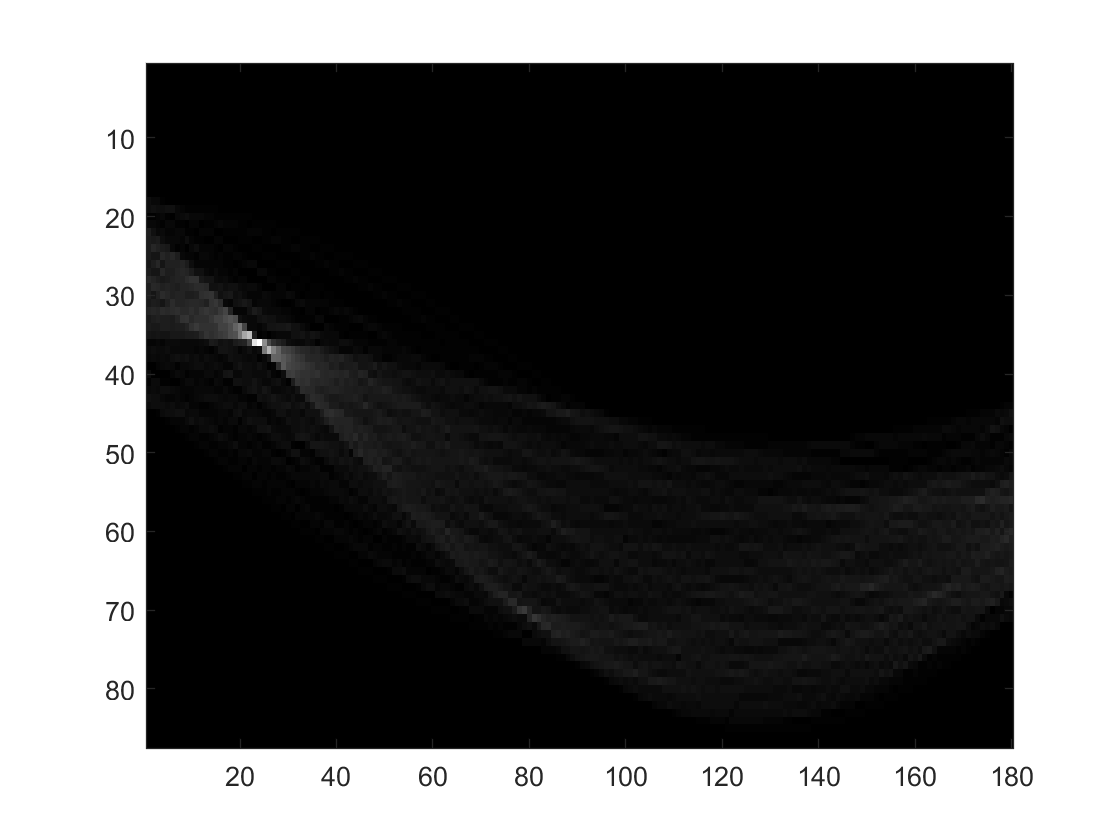

[H,theta,rho] = hough(I,'RhoResolution',3,'Theta',-90:89) ;
imagesc(H)

Here is the function for computing and plotting the Hough transform.

function H_r_theta = houghTransform(I, N_Theta, N_R)
    H_r_theta = zeros(N_R, N_Theta);
    [y, x] = find(I);
    for j = 1:length(y)
        for t = 1:N_Theta
            theta = t*2*pi/N_Theta;   % goes from 0 to 2pi
            %  r could be negative
            r_0 = round(  cos(theta)*x(j)  + sin(theta)*y(j)  );
            if (r_0 > 1 - N_R/2) && (r_0 < N_R/2 )
                H_r_theta(N_R/2 + r_0, t) = H_r_theta(N_R/2 + r_0, t) + 1;
            end
         end
    end
    
    rIndices = (1:N_R) - N_R/2;   % used for plotting
    thetaIndices = (1:N_Theta) *2*pi/N_Theta;  % used for plotting

    %  smooth it out a bit
    %g = fspecial('gaussian',1);
    %H_r_theta = filter2(g, H_r_theta);
    
    imagesc(thetaIndices,rIndices,H_r_theta)
    xlabel('\theta','FontSize',20);  ylabel('r','FontSize',20);
end